#                                                        Circuito de Chua

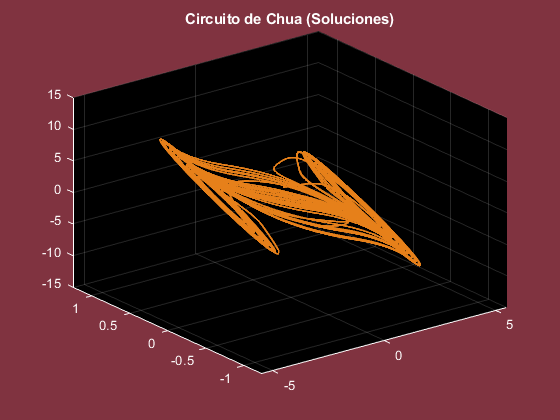

clc
clearvars
close all
format short

global m1 m2 lamda alpha k1 k2 k3;



m1=-5/7;
m2 = -3/7;
lamda = 30; 
alpha=15.6;
k1=70;
k2=32;
k3=95;

ti=0;
tf=100;
h=0.001;
t=(ti:h:tf);

x0=[0.7,0.3,0.1,0.4,0.35,0.8]; %Condiciones iniciales
[t,x]=ode45(@ss,t,x0);

plot3(x(:,1),x(:,2),x(:,3),'color',[0.9 0.5 0.1],'LineWidth',1.5)
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
title('Circuito de Chua (Soluciones)','color','w')
set(gcf,'color',[0.5 0.2 0.25])
grid on

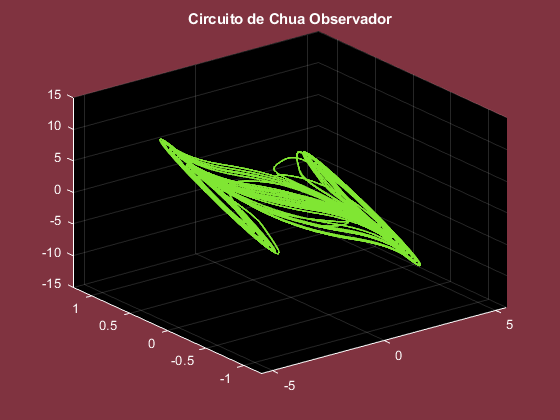



plot3(x(:,4),x(:,5),x(:,6),'color',[0.5 0.9 0.2],'LineWidth',1.5)
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
title('Circuito de Chua Observador','color','w')
set(gcf,'color',[0.5 0.2 0.25])
grid on

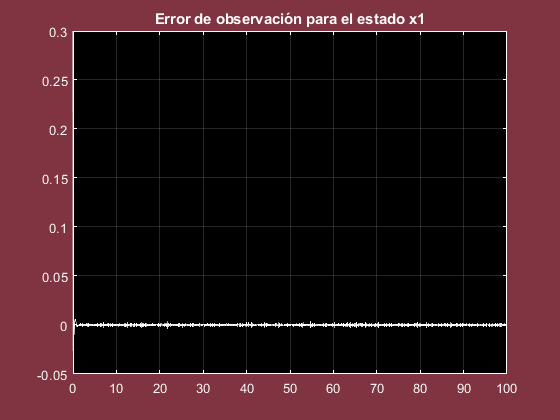



plot(t,x(:,1)-x(:,4),'w')
title('Error de observación para el estado x1','color','w') 
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

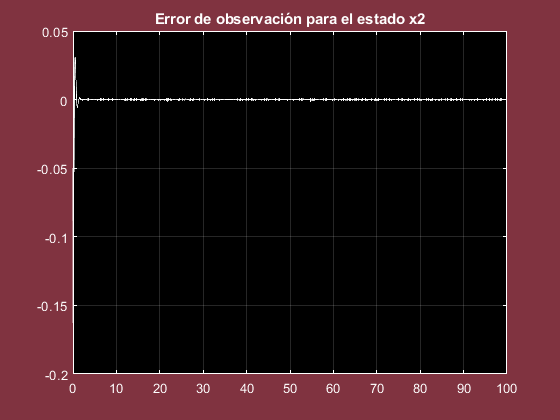



plot(t,x(:,2)-x(:,5),'w')
title('Error de observación para el estado x2','color','w') 
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

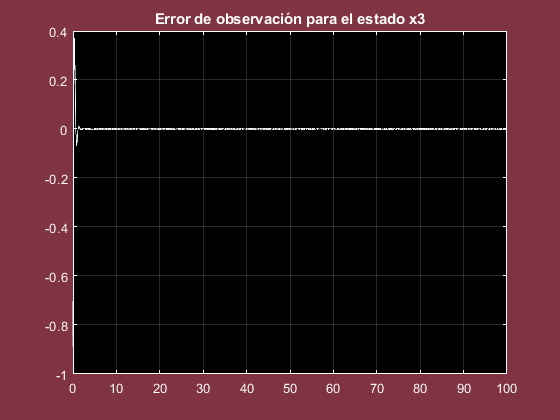


plot(t,x(:,3)-x(:,6),'w')
title('Error de observación para el estado x3','color','w') 
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

Sistema:

                                      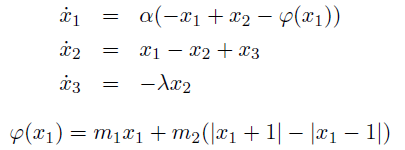

Observador:

                                                    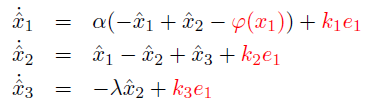

function dX=ss(t,X)

global m1 m2 lamda alpha k1 k2 k3;

phix=m1*X(1) + m2*(abs(X(1)+1) - abs(X(1)-1));
e1=X(1) - X(4);

xp1=alpha*(-X(1) + X(2) - phix);
xp2=X(1) - X(2) + X(3);
xp3=-lamda*X(2);
xpg1= alpha*(-X(4) + X(5) - phix) + k1*e1;
xpg2=X(4) - X(5) + X(6) + k2*e1;
xpg3=-lamda*X(5) + k3*e1;
dX=[xp1;xp2;xp3;xpg1;xpg2;xpg3];

end